# CS443 MATLAB Tutorial

Oliver W. Layon

Spring 2020

Numpy is heavily inspired by MATLAB so lots of functions are named the same (or similarly) and work similarly. I will give a few examples and focus on differences that might trip you up.

### Set code formatting

Please open up settings and change these defaults so that everyone has consistent code structure:

- Open Home -> Preferences

- Editor/debugger -> Tab. Change TAB SIZE and INDENT SIZE to 2. 

- Editor/debugger -> Display. Change Right-hand text limit to 120 columns.

- Editor/debugger -> Language. Se Maximum column width to 120 (from beginning of line).

- Editor/debugger -> Backup files. Make sure "Automatically creae backup files...." is checked. Save every 1 minute.

- General -> MAT files -> Select MATLAB Version 7.3.

After doing this, when you write MATLAB code in a .m file and do select-all control+I (or CMD+I on macOS) it will automatically indent things nicely and consistently for you. No manual work.

### Matrix/array data structure

The MATLAB matrix (also often called array) works like an ndarray in many respects.

**Key slicing differences from numpy:** 

- No `np.` equivilent because everything in same namespace.

- You probably want semi colons at end of lines to suppress output, but it is optional (if you omit it, MATLAB will just print the result of the line).

- No such thing as something with shape (4,). Like numpy matrix, arrays always at least 2D.

- COMMAS separate elements in same ROW, SEMICOLONS separate elements into new COLUMNS

Show:

- zeros

- ones

- linspace

- rand

- Manually create matrix with prespecified elements

a = zeros(10, 1)

a =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


ones(1, 10)

ans =      1     1     1     1     1     1     1     1     1     1


linspace(-5, 5, 10)

ans =    -5.0000   -3.8889   -2.7778   -1.6667   -0.5556    0.5556    1.6667    2.7778    3.8889    5.0000


rand(3, 3)

ans =     0.2142    0.6946    0.6021
    0.3024    0.8406    0.0458
    0.0290    0.0102    0.0560


m = [1, 2, 3; 4, 5, 6]

m =      1     2     3
     4     5     6


**New feature**: colon notation to quickly create a row vector.

1:10

ans =      1     2     3     4     5     6     7     8     9    10


1:0.1:5

ans =     1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000    5.0000


**Key slicing differences from numpy:** 

- MATLAB uses 1-based indexing (not 0 based indexing).

- MATLAB uses PARENTHESES (), not square brackets to access/index into an array

- When slicing, you need to always specify lower and upper bound

- `end` refers to end of array (rather than -1)

- Both slicing end points are INCLUDED.

- MATLAB is flexible with indexing into row/column vectors (e.g. 5x1 and 1x5). You can access elements the same way.

Example accessing/slicing simple vector:

a = 1:10

a =      1     2     3     4     5     6     7     8     9    10


a(1)

ans = 1

a(end)

ans = 10

a(1:3)

ans =      1     2     3


a(end-1:end)

ans =      9    10


a = ones(1, 10);
b = ones(10, 1);

a(1)

ans = 1

b(1)

ans = 1

### Shapes

**Key slicing differences from numpy:** 

- In MATLAB parlance, shape is called size.

- Equivilent of `len() `Python method is `length()`. **Behavior is different: **Python always returns length of 1st dimension, MATLAB returns the dimension of the LARGEST dimension.

Examples:

- Show length

- Show size (all or select dimensions)

a = ones(1,2,3,4,5);
size(a)

ans =      1     2     3     4     5


size(a, [3, 4])

ans =      3     4


length(a)

ans = 5

numel(a)

ans = 120

### Arithmetic operators

- Operators + and - work as expected all the time.

- *, /, and ^ mean scalar or matrix computations (e.g. * means matrix multiply, like @ in numpy).

- Use a period before each for element-wise operations: .*, ./, .^

- Tick mark is transpose (') rather than .T

Examples to show:

- Matrix vs element-wise operators. Use transpose.

a = 1:10;
b = 21:30;

10*a

ans =     10    20    30    40    50    60    70    80    90   100


a

a =      1     2     3     4     5     6     7     8     9    10


b

b =     21    22    23    24    25    26    27    28    29    30


a .* b

ans =     21    44    69    96   125   156   189   224   261   300


a ./ b

ans =     0.0476    0.0909    0.1304    0.1667    0.2000    0.2308    0.2593    0.2857    0.3103    0.3333


### Concatenating vectors/matrices

Show examples of:

- Use matrix notation to concatenate across rows

- Use matrix notation to concatenate across cols

- Use general function otherwise

a = 1:10;
b = 21:30;
size(a)

ans =      1    10


size(b)

ans =      1    10


% vertical concatenation - add b as second row
size([a; b])

ans =      2    10


% horizontal concatenation - add b as additional columns
size([a, b])

ans =      1    20


c = rand(1,2,3);
d = rand(1,2,3);
size(cat(3, c, d))

ans =      1     2     6


### Axes

- Axes work like in numpy. Note 1-based indexing.

**Key difference from numpy:** 

- Functions like sum without axis by default only operate over 1st dimension in MATLAB. In python, you sum across all dimensions.

a = rand(2,3,4);
size(squeeze(sum(a, 1)))

ans =      3     4


size(sum(a, 3))

ans =      2     3


size(sum(a))

ans =      1     3     4


sum(a, "all")

ans = 14.1013

sum(a(:))

ans = 14.1013

### Singleton dimensions and binary singleton expansion

Numpy broadcasting = MATLAB binary singleton expansion.

Fastest way (compiled directly to optimized C code) to do element-wise vectorized operations (do matrix operations otherwise).

**Key slicing differences from numpy:** 

- MATLAB will automatically add singleton dimensions on RIGHT HAND SIDE dimensions.

- Add "new axis" to left by using the `shiftdim`

Show example:

- Do weighted sum of some RGB images (generate fake random data).

- Use shiftdim to apply weight to color channel

imgs = rand(20, 256, 256, 3);
wts = 1:20;
size(imgs)

ans =     20   256   256     3


size(wts)

ans =      1    20


size(wts')

ans =     20     1


size(imgs .* wts')

ans =     20   256   256     3


size(sum(imgs .* wts'))

ans =      1   256   256     3


rgb_wts = 1:3;
size(rgb_wts)

ans =      1     3


size(shiftdim(rgb_wts, -2))

ans =      1     1     1     3


size(shiftdim(rgb_wts, -2) .* imgs)

ans =     20   256   256     3


size(sum(shiftdim(rgb_wts, -2) .* imgs, 4))

ans =     20   256   256


### Loops and if statements

MATLAB has its roots in FORTRAN, which is different than C-like languages. Doesn't really matter too much in practice, EXCEPT:

- "end" closing syntax for for/if blocks

- memory: data stored in memory contiguously in the same COLUMN (*column major order*). In C/Java/Python, data stored contiguously along ROWS (*row major order*)

- Flattening order: Stuff in the same column gets placed next to each other.

Show examples of:

- For loop

- if/elseif/else (in loop)

- Create vector, reshape to matrix, flatten it.

a = 1:10;

for i = 1:length(a)
    if i < 4
        a(i) = 1;
    elseif i >= 4 && i < 7
        a(i) = 2;
    else
        a(i) = 3;
    end
end
disp(a)

     1     1     1     2     2     2     3     3     3     3



b = 1:6;
b

b =      1     2     3     4     5     6


b = reshape(b, [2, 3])

b =      1     3     5
     2     4     6


b(:)

ans =      1
     2
     3
     4
     5
     6


### Indexing and logical indexing

- Logical indexing works in MATLAB mostly like in Python

- `find `function gives you index of certain elements or locations of "true" elements in array. Returns the LINEAR index of elements in array.

- Linear indices go down COLUMNS 1st (remember, column major order).

- Can use ind2sub to convert to subscripts.

Show example of:

- Logical indexing

- Find

- Access by linear index

- Use `ind2sub`

a = 1:10;
a(a > 3) = 99;
a

a =      1     2     3    99    99    99    99    99    99    99


m = magic(3)

m =      8     1     6
     3     5     7
     4     9     2


find(m > 5)

ans =      1
     6
     7
     8


m(find(m > 5))

ans =      8
     9
     6
     7


[r, c] = ind2sub(size(m), find(m > 5));
r

r =      1
     3
     1
     2


c

c =      1
     2
     3
     3


### Function handles / anonymous function

Usually, you have to create a new file for every function that you write in MATLAB (format: `function_name.m`). If you have a function that is short and just want to use in one a script or function, easier to just make a **anonymous function **(lambda function in other languages). Needs to be a one-liner.

- Function handle is the @ symbol.

Show example of:

- Anonymous function to apply the function: $f(x_1, x_2, x_3) = 10x_1^2+5x_2+x_3$

a = 1:10;
b = 21:30;
c = 31:40;

fx = @(x1, x2, x3) 10*x1.^2 + 5*x2 + x3;

fx(a, b, c)

ans =          146         182         238         314         410         526         662         818         994        1190


### Strings and character arrays

- For many years (like unit 2017!), strings were represented in MATLAB as character arrays (ala C). You might be surprised to discover that this wasn't a big deal (honestly, it's not as painful as it sounds), but strings have been recently added at a native data type.

- Most MATLAB code out there assumes the older character arrays.

- Single quotes: chararacter array

- Double quotes: native string

Show examples of:

- Indexing character arrays

- Indexing string arrays

str1 = ['hi', 'cs443!'];
str1(1)

ans = 'h'

str2 = ["hi", "cs443!"];
str2(1)

ans = "hi"

### Cell arrays

- Interesting data type in MATLAB. Sort of like lists in Python (can store heterogenous data in them), but you can pre-allocate memory of them.

- Solution for getting character arrays to work like strings.

- Index using curly braces instead of paretheses

- If data homogenous, can convert to array with `cell2mat` function.

my_cell = {'Hi', 'CS443!', 1:10}

my_cell = 1×3 cell array
    {'Hi'}    {'CS443!'}    {1×10 double}


my_cell{1}

ans = 'Hi'

my_cell{3}

ans =      1     2     3     4     5     6     7     8     9    10


my_pre_cell = cell(5, 1)

my_pre_cell = 5×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


my_pre_cell 

my_pre_cell = 5×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


### Plotting

- As the name suggests matplotlib was inspired by MATLAB so the syntax/style is very similar.

Show example of:

- x and x^2 on same plot

- subplot of x and x^2 stacked in a 2x1 grid

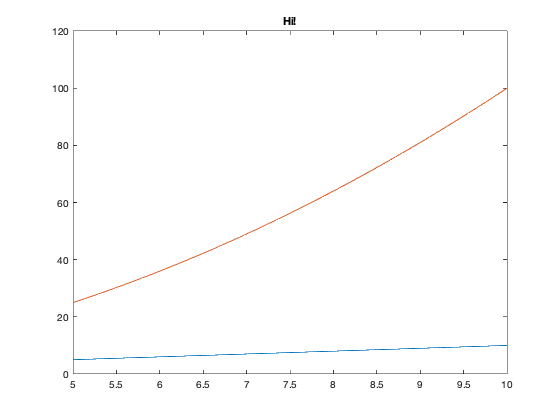

x = linspace(1, 15, 500);
plot(x, x)
hold on;
plot(x, x.^2)
title('Hi!')
xlim([5, 10])
hold off;

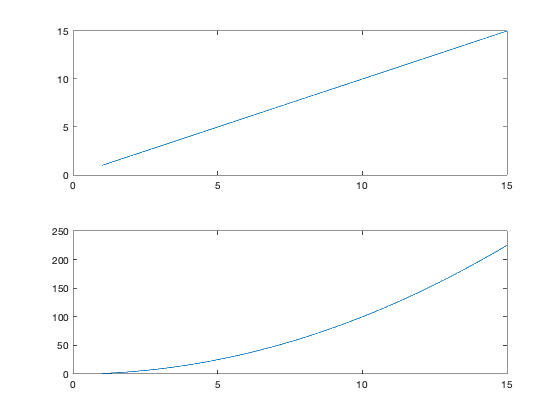

subplot(2,1, 1)
plot(x, x)
subplot(2,1, 2)
plot(x, x.^2)

### Functions

- Although Live Scripts are nice for presentations/demos/project specifications, most MATLAB coding is typically done in .m files.

- Two main types (same extension): 

- 1) scripts. Basically like one big jupyter notebook cell. Just a sequence of commands to execute. Run via "Play" button in toolbar or by running filename in Command Window. Variables stay in memory after computations done.

- 2) functions. Most common try. Pass in variables, do computations, memory cleared when done (except returned variables).

Show example of:

- Create function called `velocity.m` that takes in 2D array of vector x components and another 2D array of vector y, and a boolean whether or not to normalize the vectors by the vector Euclidean distance. Return the magnitude and angle of each vector.

- Plot the magnitude of the vectors in the function.

### MATLAB Debugger (So awesome!!!)

- Use to run and figure out what's going on in a real function I actually wrote for my research — `pooling_model.m`.